%Initial conditions
n=4;

q1=0;q2=0;q3=0;q4=0;
phi=0;psi=0;theta=0;
xG1=0;xG2=0;xG3=0;

q0=[q1;q2;q3;q4];
x0=[xG1;xG2;xG3;phi;theta;psi];

[xE0,J0] = EEKinematics(phi,psi,q1,q2,q3,q4,theta,xG1,xG2,xG3);
xEEDot0=[0;0.1;0;0;0;0];
qDot0=pinv(J0)*xEEDot0;

H0_0=H0F(phi, psi, q1, q2, q3, q4, theta);
H0m_0=H0m(phi, psi, q1, q2, q3, q4, theta);
xDot0=-H0_0\H0m_0*qDot0; %use eqn 109 to find x0dot

z0=[x0;q0;xDot0;qDot0];

%Set up the integration 
T=175; tSpan=[1 T];
[tSol,zSol]=ode45(@(t,z) FFSMPractice(t,z), tSpan, z0);

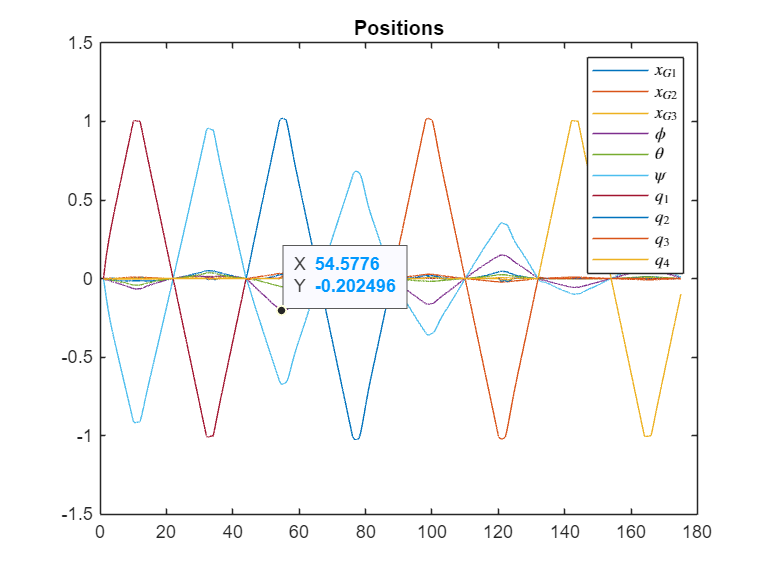

plot(tSol,zSol(:,1:10))
% hold on
% plot(tSol,zSol(:,4:6), '--')
% plot(tSol,zSol(:,7:10))
% hold off
legend('$x_{G1}$','$x_{G2}$','$x_{G3}$','$\phi$','$\theta$','$\psi$','$q_1$','$q_2$','$q_3$','$q_4$',"Interpreter","latex")
title('Positions')

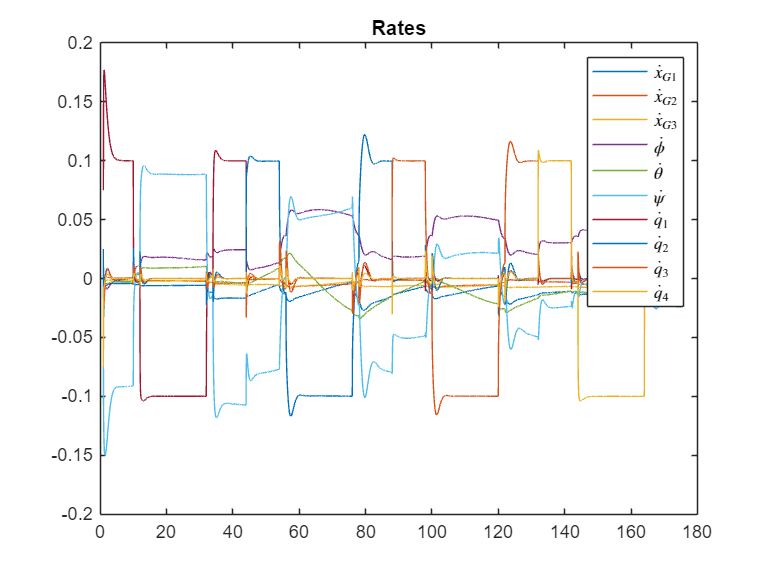

plot(tSol,zSol(:,11:20))
% plot(tSol,zSol(:,11:13), ':')
% hold on
% plot(tSol,zSol(:,14:16), '--')
% plot(tSol,zSol(:,17:20))
% hold off
legend('$\dot{x}_{G1}$','$\dot{x}_{G2}$','$\dot{x}_{G3}$','$\dot{\phi}$','$\dot{\theta}$','$\dot{\psi}$','$\dot{q}_1$','$\dot{q}_2$','$\dot{q}_3$','$\dot{q}_4$',"Interpreter","latex")
title('Rates')

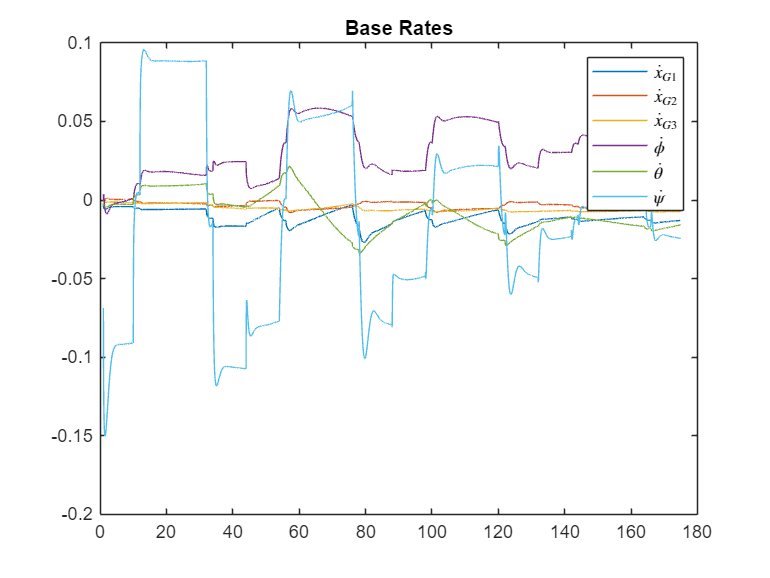

plot(tSol,zSol(:,11:16))
% hold on
% plot(tSol,zSol(:,14:16))
% hold off
legend('$\dot{x}_{G1}$','$\dot{x}_{G2}$','$\dot{x}_{G3}$','$\dot{\phi}$','$\dot{\theta}$','$\dot{\psi}$',"Interpreter","latex")
title('Base Rates')

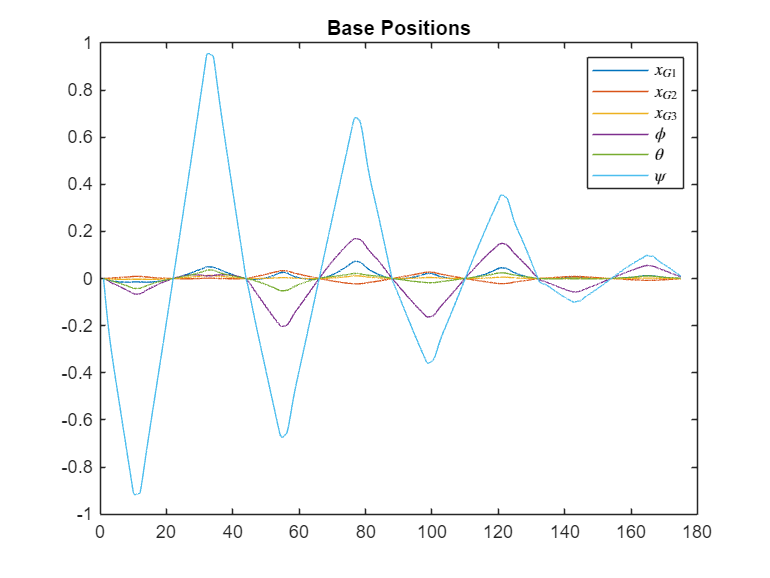

plot(tSol,zSol(:,1:6))
% hold on
% plot(tSol,zSol(:,4:6))
% hold off
legend('$x_{G1}$','$x_{G2}$','$x_{G3}$','$\phi$','$\theta$','$\psi$',"Interpreter","latex")
title('Base Positions')

% nameSpec1='$x_{G%d}$';
% i=1; 
% name=sprintf(nameSpec1,i);
% plot(tSol,zSol(:,i), 'DisplayName',name)
% hold on
% for i=2:3
% name=sprintf(nameSpec1,i);
% plot(tSol,zSol(:,i), 'DisplayName',name)
% end
% name2=["$\phi$"; "$\theta$"; "$\psi$"];
% for i=1:3
%     plot(tSol, zSol(:,i+3), 'DisplayName',name2(i))
% end
% legend('Interpreter','latex')
% for i=1:3
% 
%     name=sprintf(nameSpec,i);
%     plot(tSol,zSol(:,i), 'DisplayName',name)


function zDot=FFSMPractice(t,z)
n=4;
kp=1; kd=1; %from the paper.

xG1=z(1);xG2=z(2);xG3=z(3);
phi=z(4); theta=z(5); psi=z(6);
q1=z(7);q2=z(8);q3=z(9);q4=z(10);

xG_dot1=z(11); xG_dot2=z(12); xG_dot3=z(13);

% Assume angular velocity matrix is already included in calculations
phi_dot=z(14); theta_dot=z(15); psi_dot=z(16); 

q_dot1=z(17);q_dot2=z(18);q_dot3=z(19);q_dot4=z(20);

q=[q1;q2;q3;q4];
q_dot=[q_dot1;q_dot2;q_dot3;q_dot4];

H0T=H0F(phi, psi, q1, q2, q3, q4, theta);
H0mT=H0m(phi, psi, q1, q2, q3, q4, theta);
HmT=HmF(q2, q3, q4);

HStarT=HmT-H0mT'*(H0T\H0mT);

H0DotT =  H0dot(phi,phi_dot,psi,psi_dot,q1,q2,q3,q4,q_dot1,q_dot2,q_dot3,q_dot4,theta,theta_dot);
HmDotT = HmDot(phi,phi_dot,psi,psi_dot,q1,q2,q3,q4,q_dot1,q_dot2,q_dot3,q_dot4,theta,theta_dot);
H0mDotT = H0mdot(phi,phi_dot,psi,psi_dot,q1,q2,q3,q4,q_dot1,q_dot2,q_dot3,q_dot4,theta,theta_dot);

HStarDotT=HmDotT-(H0mDotT'*(H0T\H0mT) + H0mT'*(H0T\H0mDotT) - H0mT'*(H0T\H0DotT)*(H0T\H0mT));

dH0dqT = dH0dq(phi,psi,q1,q2,q3,q4,theta);
dHmdqT = dHmdq(phi,psi,q1,q2,q3,q4,theta);
dH0mdqT = dH0mdq(phi,psi,q1,q2,q3,q4,theta);

for k=1:n
    dHmdq_k=dHmdqT(:,:,k);
    dH0dq_k=dH0dqT(:,:,k);
    dH0mdq_k=dH0mdqT(:,:,k);

    dHStardq_k = dHmdq_k - dH0mdq_k'*(H0T\H0mT) - H0mT'*(H0T\dH0mdq_k) + H0mT'*(H0T\dH0dq_k)*(H0T\H0mT);

    dHStardqT(:,:,k)=dHStardq_k;

    cStar1_k=-0.5*q_dot'*dHStardq_k*q_dot;
    cStar1(k,:)=cStar1_k;
end
CStar2 = HStarDotT*q_dot + cStar1;

zD=cTrajectory(t);
qD=zD(1:n);
qD_dot=zD(n+1:2*n);
u=kp*(qD-q) + kd*(qD_dot-q_dot); 

q_ddot=HStarT\(-CStar2 + u);
%Big problem. WTD for x_ddot?
%Maybe I need the generalized Jacobian after all
%Try taking time derivative of eqn 109
x0_ddot=(H0T\H0DotT)*(H0T\H0mT)*q_dot - (H0T\H0mDotT)*q_dot - (H0T\H0mT)*q_ddot;
x0_dot=-H0T\H0mT*q_dot;

zDot=[x0_dot;q_dot;x0_ddot;q_ddot];




end